Grant Roberts

03/11/2019

MP574

# Homework 3

## Problem 1: Reconstruction from Partial Fourier Samples without Regularization

**Write a script that loads the data in **`hw3_problem1.mat`**, and reconstructs an image of size 320x320 pixels from the samples in array** `b`. The samples are DFT samples of the image, taken at the locations specified by the mask in array `mask`. In other words, the matrix $\mathbf{A}$ in our general formulation (equation 1 above) is 


$$\mathbf{A}=\mathbf{MF}$$


where $\mathbf{F}$ performs a 2D DFT (including `fftshifts` and `ifftshifts`) and the matrix $\mathbf{M}$ is a sampling matrix that selects a subset of samples from the resulting 320x320 2D DFT. The selected subset of samples is given by the binary array `m`.

In this case, there is no regularization term (ie: $\lambda =0$).

#### Load Data

clear all; close all;
load('hw3_problem1.mat')

dims = 320;
N = dims*dims;
imageSize = [320 320];
tol = 0.01; % tolerance (for approximate convergence)
iters = 100;

B(m) = b; B = B(:); % zero padded data vector
tru = rearrange(B,dims); % original kSpace data

#### Steepest Descent

%alpha = zeros(1,iters); % Initialize alpha matrix
x_in = zeros(N,iters+1); % Initialize kSpace matrix
f = zeros(1,iters); % initialize cost function values

tic
for ii=1:iters
    f(ii) = f1(x_in(:,ii),b,m,dims); % cost function output
    df = df1(x_in(:,ii),B,m,dims); % gradient at input x
    alpha = goldenSearch(x_in(:,ii),df,b,m,dims); % find alpha for this x
    x_in(:,ii+1) = x_in(:,ii) - alpha*df; % find new x
    if norm(df) < tol % if gradient is near 0
        break; % the solution converged
    end    
end 
toc

Elapsed time is 1.728317 seconds.



f = f(1:ii); % cutoff trailing zeros
solution1 = x_in(:,ii);

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

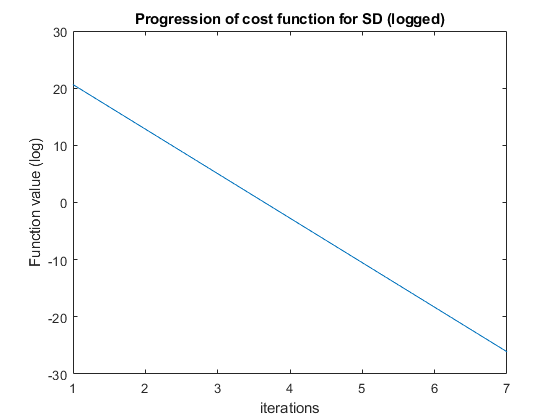

figure; plot(log(f)); 
title('Progression of cost function for SD (logged)'); xlabel('iterations'); ylabel('Function value (log)')

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

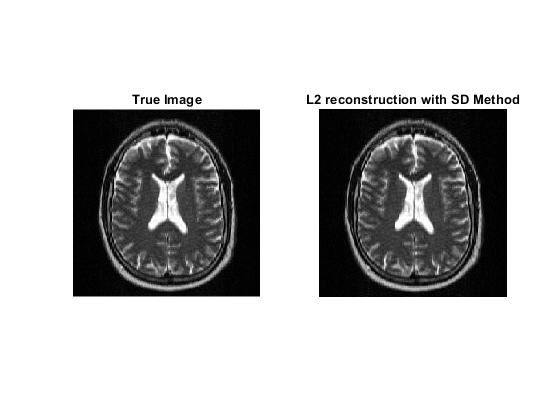

% Show image solution
figure; subplot(1,2,1)
imshow(abs(ifft2c(rearrange(tru,dims))),[0 1]); title 'True Image'; 
subplot(1,2,2)
imshow(rearrange(abs(solution1),dims),[0 1]); title 'L2 reconstruction with SD Method'

#### Conjugate Gradients

g = zeros(N,iters+1); % initialize gradient matrix
d = zeros(N,iters+1);
f = zeros(1,iters); % initialize cost function values
solution_exists = 0; % set to false
% Note that I am performing optimization in k-space, not image space.
% Thus, Q = M^H*M, equivalent to a point-wise multiplication of the mask (m)

tic
k = 0;
% g(:,k) = df1(x_in(:,k),B,m,dims); % calculate gradient at 1st point
% d(:,k) = g(:,k); % create new d variable 
% f(k) = f1(x_in(:,k),b,m,dims);
% if norm(g(:,k)) < tol % if gradient vector is near 0 (l1 norm) at initial point
%     solution_exists = 1; % change flag to true
%     solution1 = X(:,k) % we did it
% end 
while(k < iters && solution_exists == 0)
    k = k+1;
    f(k) = f1(x_in(:,k),b,m,dims);   
    g(:,k) = df1(x_in(:,k),B,m,dims); % calculate gradient at 1st point
    d(:,k) = g(:,k); % create new d variable 
    % Get Q matrix
        dK = fft2c(rearrange(d(:,k),dims)); % kSpace d vector (Fd)
        dK = dK(:).*m; % masked kSpace d vector (M'MFd)
        Qd = ifft2c(rearrange(dK,dims)); % back to image space (F'M'MFd)
        Qd = Qd(:); % vectorize        
    alpha = -(g(:,k)')*d(:,k)/(d(:,k)'*Qd); % find next stepsize
    x_in(:,k+1) = x_in(:,k) + alpha*d(:,k); % move that stepsize in direction of gradient (d).
    g(:,k+1) = df1(x_in(:,k+1),B,m,dims); % redefine gradient
    if norm(g(:,k+1)) < tol % if gradient is near 0
        solution_exists = 1; % BREAK        
    else 
        beta = (g(:,k+1)')*Qd/(d(:,k)'*Qd); % find next-next step
        d(:,k+1) = -g(:,k+1) + beta*d(:,k); % second gradient move
    end
end 

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

toc

f = f(1:k); % cutoff trailing zeros
solution1 = x_in(:,k); % grab solution

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

figure; plot(log(f)); 
title('Progression of cost function for CG (logged)'); xlabel('iterations'); ylabel('Function value (log)')

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

% Show kSpace solution
figure; subplot(1,2,1)
imshow(log(abs(tru)),[0 12]); title 'True kSpace Data';
subplot(1,2,2)
imshow(log(abs(rearrange(solution1,dims))),[0 12]); title 'L2 reconstruction'

% Show image solution
figure; subplot(1,2,1)
imshow(abs(ifft2c(rearrange(tru,dims))),[0 1]); title 'True Image';
subplot(1,2,2)
imshow(abs(ifft2c(rearrange(solution1,dims))),[0 1]); title 'L2 reconstruction with CG Method'

- **Report the relative performance of SD and CG (ie: how rapidly do they converge).**

disp(['Steepest Descent Method converged in ' num2str(ii) ' iterations']);
disp(['Conjugate Gradient Method converged in ' num2str(k-1) ' iterations']);

The CG method was slightly quicker in reaching the global optimum, but both were fairly quick. The SD method took slightly longer (340 ms) to converge, while the CG method took approximately 280 ms to converge.

## Problem 2: Reconstruction from Partial Fourier Samples with Smoothness Regularization

**Write a script that loads the data in **`hw3_problem2.mat`**, and reconstructs an image (320x320 pixels) from the samples in array **`b`. Next we describe the data and smoothness terms:

• Data term: Similar to the previous case, the samples in `b` are DFT samples of the image, taken at the locations specified by the mask in array `mask`. In other words, the matrix $\mathbf{A}$ in our general formulation (equation 1 above) is


$$\mathbf{A}=\mathbf{MF}$$


where $\mathbf{F}$ performs a DFT (including `fftshifts`) and the matrix $\mathbf{M}$ is a sampling matrix that selects a subset of samples from the resulting 320x320 DFT. The selected subset of samples is given by the binary array `m`.

• Smoothness term: The smoothness term is given by $\lambda \;{\left\|\textrm{Cx}\right\|}_2^2$, where $\mathbf{C}=\mathbf{D}$ calculates finite differences in 2D, as described in lecture 14 of this course (where we denoted it as `D2` in the Matlab code to indicate its 2D nature).

You should **repeat this optimization for several different values of **$\lambda$:

• $\lambda ={10}^0$

• $\lambda ={10}^2$

• $\lambda ={10}^4$

• $\lambda ={10}^6$

• $\lambda ={10}^8$

lambda = [10^0 10^2 10^4 10^6 10^8];

% Create D (finite differences matrix)
D = 2*eye(dims) - circshift(eye(dims),[0, -1]) - circshift(eye(dims),[0, 1]);
D = sparse(D);
I = speye(dims);
D2 = kron(I,D) + kron(D,I);

#### Steepest Descent

alpha = zeros(1,iters); % Initialize alpha matrix
x_in = zeros(N,iters+1); % Initialize kSpace matrix
f = zeros(1,iters); % initialize cost function values

tic
for ll = 1:length(lambda)
    for ii=1:iters
        f(ii) = f2(x_in(:,ii),b,m,D2,lambda(ll));
        df = df2(x_in(:,ii),B,m,D2,lambda(ll));
        if norm(df) < tol % if gradient is near 0
            break; % the solution converged
        end
        alpha(ii) = goldenSearch2(x_in(:,ii),df,b,m,D2,lambda(ll)); % Find alpha for this k
        x_in(:,ii+1) = x_in(:,ii) - alpha(ii)*df; % Find new k        
    end 
end 
toc

f = f(1:ii); % cutoff trailing zeros
solution1 = x_in(:,ii);

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

figure; plot(log(f)); 
title('Progression of cost function for SD (logged)'); xlabel('iterations'); ylabel('Function value (log)')

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

% Show kSpace solution
figure; subplot(1,2,1)
imshow(log(abs(tru)),[0 12]); title 'True kSpace Data';
subplot(1,2,2)
imshow(log(abs(rearrange(solution1,dims))),[0 12]); title 'L2 reconstruction'

% Show image solution
figure; subplot(1,2,1)
imshow(abs(ifft2c(rearrange(tru,dims))),[0 1]); title 'True Image';
subplot(1,2,2)
imshow(abs(ifft2c(rearrange(solution1,dims))),[0 1]); title 'L2 reconstruction with SD Method'

#### Conjugate Gradients

g = zeros(N,iters+1); % initialize gradient matrix
d = zeros(N,iters+1);
f = zeros(1,iters); % initialize cost function values
solution_exists = 0; % set to false
% Note that I am performing optimization in k-space, not image space.
% Thus, Q = M^H*M, equivalent to a point-wise multiplication of the mask (m)

tic
k = 1;
g(:,k) = df1(x_in(:,k),B,m,dims); % calculate gradient at 1st point
d(:,k) = g(:,k); % create new d variable 
f(k) = f1(x_in(:,ii),b,m);
if norm(g(:,k)) < tol % if gradient vector is near 0 (l1 norm) at initial point
    solution_exists = 1; % change flag to true
    solution1 = X(:,k) % we did it
end 
while(k <= iters && solution_exists == 0)
    f(k) = f1(x_in(:,ii),b,m);
    alpha = -(g(:,k)')*d(:,k)/(d(:,k)'*(m.*d(:,k))); % find next stepsize
    x_in(:,k+1) = x_in(:,k) + alpha*d(:,k); % move that stepsize in direction of gradient (d).
    g(:,k+1) = df1(x_in(:,k+1),B,m,dims); % redefine gradient
    if norm(g(:,k+1)) < tol % if gradient is near 0
        solution_exists = 1; % BREAK
        solution1 = x_in(:,k+1); % grab solution
    else 
        beta = (g(:,k+1)')*(m.*d(:,k))/(d(:,k)'*(m.*d(:,k))); % find next-next step
        d(:,k+1) = -g(:,k+1) + beta*d(:,k); % second gradient move
    end
    k = k+1;
end 
toc

f = f(1:k-1); % cutoff trailing zeros

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

figure; plot([0 1],[0 log(f)]); 
title('Progression of cost function for CG (logged)'); xlabel('iterations'); ylabel('Function value (log)')

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

% Show kSpace solution
figure; subplot(1,2,1)
imshow(log(abs(tru)),[0 12]); title 'True kSpace Data';
subplot(1,2,2)
imshow(log(abs(rearrange(solution1,dims))),[0 12]); title 'L2 reconstruction'

% Show image solution
figure; subplot(1,2,1)
imshow(abs(ifft2c(rearrange(tru,dims))),[0 1]); title 'True Image';
subplot(1,2,2)
imshow(abs(ifft2c(rearrange(solution1,dims))),[0 1]); title 'L2 reconstruction with CG Method'

- **Report the relative performance of SD and CG (ie: how rapidly do they converge).**

disp(['Steepest Descent Method converged in ' num2str(ii) ' iterations']);
disp(['Conjugate Gradient Method converged in ' num2str(k-1) ' iterations']);

The CG method was slightly quicker in reaching the global optimum, but both were fairly quick. The SD method took slightly longer (340 ms) to converge, while the CG method took approximately 280 ms to converge.

- **How does the final value of the cost function change as **$\lambda$** increases? How does the visual appearance of the image change as **$\lambda$** increases? **

## Problem 3: Reconstruction from Partial Fourier Samples with Anatomically-Informed Smoothness Regularization 

**Write a script that loads the data in **`hw3_problem3.mat`**, and reconstructs an image (320x320 pixels) from the samples in array **`b`. Next we describe the data and smoothness terms:

• Data term: Similar to the previous case, the samples in `b` are DFT samples of the image, taken at the locations specified by the mask in array `mask`. In other words, the matrix $\mathbf{A}$ in our general formulation (equation 1 above) is


$$\mathbf{A}=\mathbf{MF}$$


where $\mathbf{F}$ performs a DFT (including `fftshifts`) and the matrix $\mathbf{M}$ is a sampling matrix that selects a subset of samples from the resulting 320x320 DFT. The selected subset of samples is given by the binary array `m`.

• Smoothness term: The smoothness term is given by $\lambda \;{\left\|\textrm{Cx}\right\|}_2^2$, where $\mathbf{C}=\mathbf{WD}$ calculates weighted finite differences in 2D. The matrix $\mathbf{D}$, similarly to the previous problem, is as described in lecture 14 of this course (where we denoted it as `D2` in the Matlab code to indicate its 2D nature). The weighting matrix $\mathbf{W}$ is a diagonal matrix with weights derived from an image of the same anatomy as our desired image: it specifies in which locations we will penalize roughness, and in which locations (those with expected edges) we will not penalize roughness. The diagonal elements of this matrix can be found in array `w`.

You should **repeat this optimization for several different values of **$\lambda$:

• $\lambda ={10}^0$

• $\lambda ={10}^2$

• $\lambda ={10}^4$

• $\lambda ={10}^6$

• $\lambda ={10}^8$

and, in each case, **report the cost function as a function of iterations (plot), as well as the final estimated image (display)**. This should be done **for both the SD and the CG algorithms**.

#### Steepest Descent

alpha = zeros(1,iters); % Initialize alpha matrix
x_in = zeros(N,iters+1); % Initialize kSpace matrix
f = zeros(1,iters); % initialize cost function values

tic
for ii=1:iters
    f(ii) = f1(x_in(:,ii),b,m);
    df = df1(x_in(:,ii),B,m,dims);
    if norm(df) < tol % if gradient is near 0
        break; % the solution converged
    end
    alpha(ii) = goldenSearch(x_in(:,ii),df,b,m,dims); % Find alpha for this k
    x_in(:,ii+1) = x_in(:,ii) - alpha(ii)*df; % Find new k
    
end 
toc

f = f(1:ii); % cutoff trailing zeros
solution1 = x_in(:,ii);

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

figure; plot(log(f)); 
title('Progression of cost function for SD (logged)'); xlabel('iterations'); ylabel('Function value (log)')

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

% Show kSpace solution
figure; subplot(1,2,1)
imshow(log(abs(tru)),[0 12]); title 'True kSpace Data';
subplot(1,2,2)
imshow(log(abs(rearrange(solution1,dims))),[0 12]); title 'L2 reconstruction'

% Show image solution
figure; subplot(1,2,1)
imshow(abs(ifft2c(rearrange(tru,dims))),[0 1]); title 'True Image';
subplot(1,2,2)
imshow(abs(ifft2c(rearrange(solution1,dims))),[0 1]); title 'L2 reconstruction with SD Method'

#### Conjugate Gradients

g = zeros(N,iters+1); % initialize gradient matrix
d = zeros(N,iters+1);
f = zeros(1,iters); % initialize cost function values
solution_exists = 0; % set to false
% Note that I am performing optimization in k-space, not image space.
% Thus, Q = M^H*M, equivalent to a point-wise multiplication of the mask (m)

tic
k = 1;
g(:,k) = df1(x_in(:,k),B,m,dims); % calculate gradient at 1st point
d(:,k) = g(:,k); % create new d variable 
f(k) = f1(x_in(:,ii),b,m);
if norm(g(:,k)) < tol % if gradient vector is near 0 (l1 norm) at initial point
    solution_exists = 1; % change flag to true
    solution1 = X(:,k) % we did it
end 
while(k <= iters && solution_exists == 0)
    f(k) = f1(x_in(:,ii),b,m);
    alpha = -(g(:,k)')*d(:,k)/(d(:,k)'*(m.*d(:,k))); % find next stepsize
    x_in(:,k+1) = x_in(:,k) + alpha*d(:,k); % move that stepsize in direction of gradient (d).
    g(:,k+1) = df1(x_in(:,k+1),B,m,dims); % redefine gradient
    if norm(g(:,k+1)) < tol % if gradient is near 0
        solution_exists = 1; % BREAK
        solution1 = x_in(:,k+1); % grab solution
    else 
        beta = (g(:,k+1)')*(m.*d(:,k))/(d(:,k)'*(m.*d(:,k))); % find next-next step
        d(:,k+1) = -g(:,k+1) + beta*d(:,k); % second gradient move
    end
    k = k+1;
end 
toc

f = f(1:k-1); % cutoff trailing zeros

- **Plot the (logarithm of the) value of the cost function (**${\left\|\mathrm{Ax}-b\right\|}_2^2 +{\lambda \;\left\|\mathrm{Cx}\right\|}_2^2$**) as a function of iterations (this should be decreasing for both algorithms, but different between algorithms). Since the value of the cost function will likely change a lot, make sure to plot its logarithm vs the iteration number.**

figure; plot([0 1],[0 log(f)]); 
title('Progression of cost function for CG (logged)'); xlabel('iterations'); ylabel('Function value (log)')

- **Plot the final image after the iterations are done for each of the algorithms (display it using a common colormap for both algorithms).**

% Show kSpace solution
figure; subplot(1,2,1)
imshow(log(abs(tru)),[0 12]); title 'True kSpace Data';
subplot(1,2,2)
imshow(log(abs(rearrange(solution1,dims))),[0 12]); title 'L2 reconstruction'

% Show image solution
figure; subplot(1,2,1)
imshow(abs(ifft2c(rearrange(tru,dims))),[0 1]); title 'True Image';
subplot(1,2,2)
imshow(abs(ifft2c(rearrange(solution1,dims))),[0 1]); title 'L2 reconstruction with CG Method'

- **Report the relative performance of SD and CG (ie: how rapidly do they converge).**

disp(['Steepest Descent Method converged in ' num2str(ii) ' iterations']);
disp(['Conjugate Gradient Method converged in ' num2str(k-1) ' iterations']);

The CG method was slightly quicker in reaching the global optimum, but both were fairly quick. The SD method took slightly longer (340 ms) to converge, while the CG method took approximately 280 ms to converge.

- **How does the final value of the cost function change as **$\lambda$** increases? How does the visual appearance of the image change as **$\lambda$** increases? How do the cost function and visual appearance of the image in this problem compare to those in the previous problem?**

### ANCILLARY FUNCTIONS

Inverse Fourier transform with shifts

function x = ifft2c(k)
    x = ifftshift(ifft2(fftshift(k)));
end

Forward Fourier transform with shifts

function k = fft2c(x)
    k = fftshift(fft2(ifftshift(x)));
end

Rearrange vector into 2D matrix for Fourier transform

function matrix = rearrange(vector,dims)
    matrix = reshape(vector,[dims dims]);
end